% AAE 532 HW 6 Problem 2
% Tomoki Koike
close all; clear all; clc;
fdir = 'C:\Users\Tomo\Desktop\studies\2020-Fall\AAE532\matlab\outputs\ps6';
set(groot, 'defaulttextinterpreter','latex');
set(groot, 'defaultAxesTickLabelInterpreter','latex');
set(groot, 'defaultLegendInterpreter','latex');
format shortG;

% Set constants
planet_consts = setup_planetary_constants();  % Function that sets up all the constants in the table 
sun = planet_consts.sun;  % structure of sun
earth = planet_consts.earth;  % structure of earth
mars = planet_consts.mars;  % structure of mars
G = 6.6743015e-20;  % Gravitational constant [km^3/kg/s^2]

% (a)
Re         = earth.mer;  % Earth radius
mu         = earth.gp;  % gravitational parameter
a          = 4*Re;  % semi major axis
e          = 0.4;  % eccentricity 
p          = a * (1 - e^2);  % semi latus rectum
TA         = 135;  % true anomaly at maneuver point
r1         = p / (1 + e * cosd(TA));          
v1         = vis_viva(r1, a, mu);         
h          = sqrt(mu * p);  % specific angular momentum
FPA1       = acosd(h / r1 / v1);  % flight path angle
r1vec_i     = r1 * [cosd(TA), sind(TA)];
v1vec_o    = v1 * [sind(FPA1), cosd(FPA1)]

v1vec_o =        1.2198       3.0929


v1vec_i    = v1vec_o * [cosd(TA), sind(TA); -sind(TA), cosd(TA)]

v1vec_i =       -3.0496      -1.3245


% Maneuver 
dv = 0.90;  % km/s
alpha = 45;  % degrees
v2 = sqrt(dv^2 + v1^2 - 2*dv*v1*cosd(180 - alpha));
FPA2 = acosd(h / r1 / v2)

FPA2 =        39.563


dFPA = FPA2 - FPA1

dFPA =        18.039


v2vec_o = v2 * [sind(FPA2), cosd(FPA2)]

v2vec_o =        2.5553       3.0929


dvvec_o = v2vec_o - v1vec_o

dvvec_o =        1.3355            0


v2vec_i = v2vec_o * [cosd(TA), sind(TA); -sind(TA), cosd(TA)]

v2vec_i =       -3.9939     -0.38013


dvvec_i = dvvec_o * [cosd(TA), sind(TA); -sind(TA), cosd(TA)]

dvvec_i =      -0.94434      0.94434



v1vec_vbn = v1 * [1, 0];
v2vec_vbn = v2 * [cosd(dFPA), sind(dFPA)];
dvvec_vbn = v2vec_vbn - v1vec_vbn;

% (d)
r2 = r1;
a_new = (-mu / 2) / (v2^2/2 - mu/r2);
e_new = calc_e_posVel(r2, v2, FPA2, mu, "deg")

e_new =       0.65656


p_new = a_new*(1 - e_new^2)

p_new =         21431


h = sqrt(mu * p_new)

h =         92424


IP = 2*pi*sqrt(a_new^3 / mu)

IP =         72756


IP_day = IP / 60 /60 / 24

IP_day =       0.84208


En = -mu / 2 / a_new

En =        -5.291


TA_new = acos_dbval(1/e_new *(p_new/r2 - 1), "deg")

TA_new =        115.52      -115.52


TA_new = TA_new(TA_new >0)

TA_new =        115.52


E_new = T2E_anomaly(e_new, TA_new, "deg")

E_new =        71.651


dt = (deg2rad(E_new) - sind(E_new)) * sqrt(a_new^3 / mu)

dt =          3490


rp_new = a_new*(1 - e_new)

rp_new =         12937


Domega = TA - TA_new

Domega =        19.482


ra_new = a_new*(1 + e_new)

ra_new =         62399


rp = a*(1-e);
ra = a*(1+e);

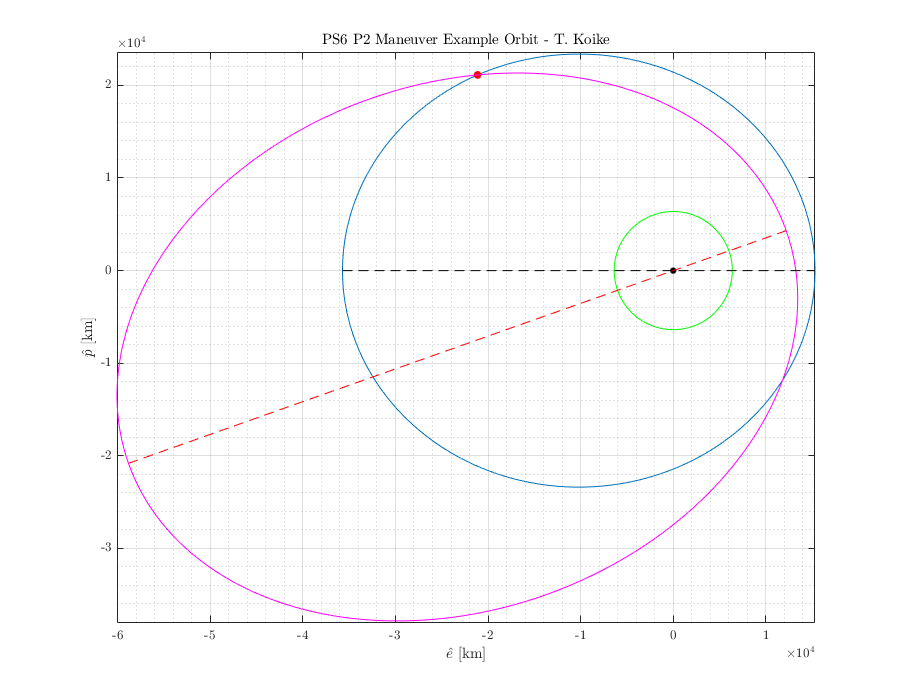

% Plotting for visualization 
% old orbit
angles = 0:0.01:2*pi;
RR = p ./ (1 + e*cos(angles)); XX = RR.*cos(angles); YY = RR.*sin(angles);

% new orbit
RR_new = p_new ./ (1 + e_new*cos(angles - deg2rad(Domega)));
XX_new = RR_new.*cos(angles);
YY_new = RR_new.*sin(angles);
rp_vec = rp_new*[cosd(Domega), sind(Domega)];
ra_vec = ra_new*[cosd(Domega+180), sind(Domega+180)];

Xearth = Re*cos(angles); Yearth = Re*sin(angles);
fig = figure("Renderer","painters","Position",[10, 10, 900, 700]);
plot(XX,YY)
hold on; grid on; grid minor; box on; axis equal; 
plot(r1vec_i(1), r1vec_i(2), '.r', 'MarkerSize', 20)
plot(0,0,'.k', 'MarkerSize', 15)
plot(Xearth, Yearth, '-g')
plot(XX_new, YY_new, '-m')
plot([-ra, rp], [0, 0], '--k')
plot([ra_vec(1), rp_vec(1)],[ra_vec(2), rp_vec(2)], '--r')
hold off
title('PS6 P2 Maneuver Example Orbit - T. Koike')
xlabel('$\hat{e}$ [km]')
ylabel('$\hat{p}$ [km]')
saveas(fig, fullfile(fdir, "p2-orbit.png"))

function e = calc_e_posVel(r, v, gamma, mu, unit)
    A = (r*v^2 / mu - 1)^2;
    if unit == "rad"
        B = cos(gamma)^2;
        C = sin(gamma)^2;
    else
        B = cosd(gamma)^2;
        C = sind(gamma)^2;
    end
    e = sqrt(A*B+C);
end